# Clustering clients with k-medoids to estimate their preferred time horizon of investment

## Objective

In this file the main objective is to segment clients in order to determine clusters of clients with similar characteristics. This information will then be used to make a plausible estimate on the time horizon of investment preferred by each client. Thus the new dataset is divided into training and testing set and two classification models are built, specifically one for the accumulation products and the other for the income ones. Then precision, recall and F1 score will be computed, confusion matrix and ROC curve will be plotted and the results will be commented.

In this case, both numerical  and categorical features are used: gender, family members, age, financial education, risk propensity, income and wealth. Therefore the clustering algorithm applied is k-medoids with hamming distance for the encoded categorical features and cityblock for numerical features.

#### *Load data *

close all
clc
load('Needs.mat') % original dataset

### Preparing data

We extract the variables of interest, also dividing into:

- numerical;

- categorical (excluding the *ID, Income Investment* and *Accumulation Investment* columns ).

We have to:

- **encode** the variable *Family members*;

- **normalize** numerical variables.

- **collect** all variables in the same matrix X.

We also make a Box Cox transformation on *Wealth *and *Income* and we choose to apply the logarithm for a clearer interpretation of results.

We have chosen to consider the whole dataset in order to have more precise results.

% Numerical features

Data = Needs(:,2:8); % Exclude 1st col = ID and Income/accumulation labels
logWealth = log(Data.Wealth); %log trasformation of data
logIncome = log(Data.Income); %log trasformation of data

XNum =[rescale(Data.Age) rescale(Data.FinancialEducation)...
    rescale(Data.RiskPropensity) rescale(logIncome) rescale(logWealth)];

% Encoding (ie create dummy variables) for family members
XCat2 = dummyvar(grp2idx(Data.FamilyMembers));
XCat2 = XCat2(:,1:end-1);
%No need to encode gender

Let's put all the features together in a matrix and start doing clustering analysis.

X = [Data.Gender XCat2 XNum];

## Unsupervised clustering with mixed categorical and numerical data

### Clustering witk k-medoids

NOTE: it will take a while to run this part.

We decided to set a varying number of clusters, between 3 to 10, and then compare the results.

Since the `kmedoids` function is not guaranteed to converge to a global minimum for the problem, we will set the hyperparameter `'replicates'` to 5, so that the algorithm is run 5 times and the best result is returned. 

#### **3 clusters**

[IDX3, C3, SUMD3, D3, MIDX3, INFO3] = kmedoids(X,3,'Distance', @MixDistance,'replicates',5);

#### **4 clusters**

[IDX4, C4, SUMD4, D4, MIDX4, INFO4] = kmedoids(X,4,'Distance', @MixDistance,'replicates',5);

#### **5 clusters**

[IDX5, C5, SUMD5, D5, MIDX5, INFO5] = kmedoids(X,5,'Distance', @MixDistance,'replicates',5);

#### **6 clusters**

[IDX6, C6, SUMD6, D6, MIDX6, INFO6] = kmedoids(X,6,'Distance', @MixDistance,'replicates',5);

#### **7 clusters**

[IDX7, C7, SUMD7, D7, MIDX7, INFO7] = kmedoids(X,7,'Distance', @MixDistance,'replicates',5);

#### **8 clusters**

[IDX8, C8, SUMD8, D8, MIDX8, INFO8] = kmedoids(X,8,'Distance', @MixDistance,'replicates',5);

#### **9 clusters**

[IDX9, C9, SUMD9, D9, MIDX9, INFO9] = kmedoids(X,9,'Distance', @MixDistance,'replicates',5);

#### **10 clusters**

[IDX10, C10, SUMD10, D10, MIDX10, INFO10] = kmedoids(X,10,'Distance', @MixDistance,'replicates',5);

#### Clustering evaluation

We will use three criteria to evaluate the best number of clusters to consider for our problem.

**Calinski-Harabasz criterion** 

clust = [IDX3 IDX4 IDX5 IDX6 IDX7 IDX8 IDX9 IDX10];
eva1 = evalclusters(X,clust,'CalinskiHarabasz');
figure
plot(eva1)
eva1

The plot shows that the highest Calinski-Harabasz value occurs at 3 clusters, suggesting that the optimal number of clusters is 3.

**Davies-Bouldin criterion** 

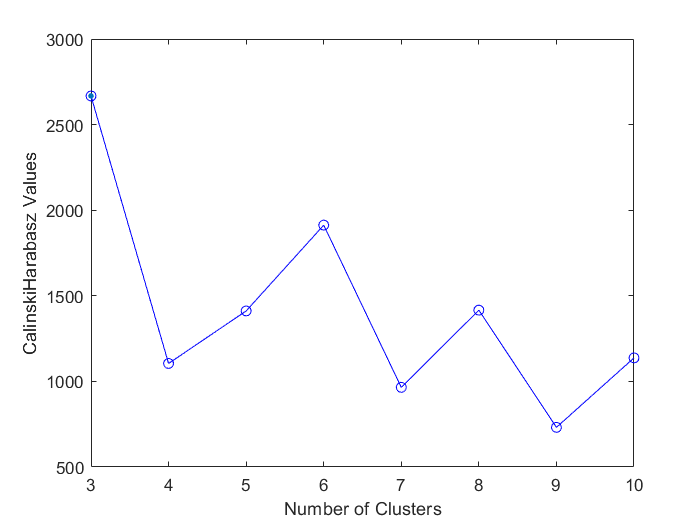

eva2 = evalclusters(X,clust,'DaviesBouldin');
figure
plot(eva2)
eva2

The plot shows that the lowest Davies-Bouldin value occurs at 3 clusters, suggesting that the optimal number of clusters is 3.

**Silhouette criterion** 

Let's have a closer look at the silhouette of the most reasonable clusters hypothesis.

figure

eva1 =   CalinskiHarabaszEvaluation with properties:

    NumObservations: 5000
         InspectedK: [3 4 5 6 7 8 9 10]
    CriterionValues: [2.6673e+03 1.1048e+03 1.4116e+03 1.9128e+03 965.2986 1.4161e+03 731.6928 1.1374e+03]
           OptimalK: 3


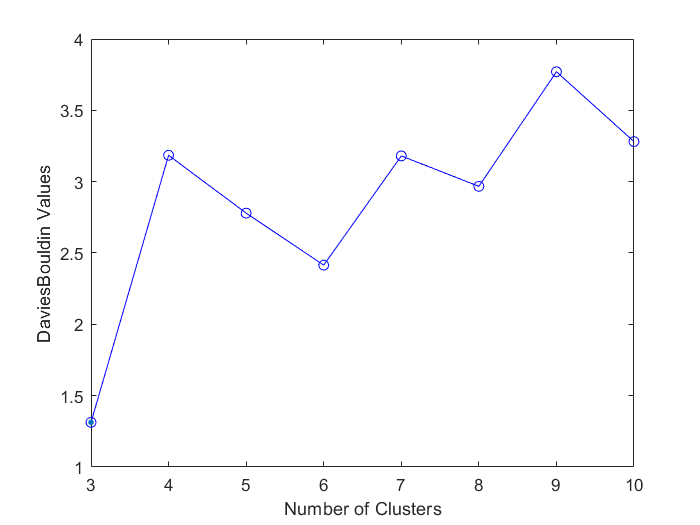

silhouette(X,IDX3, @MixDistance); % 3 is the perfect number of clusters
figure
silhouette(X,IDX4, @MixDistance); 
figure
silhouette(X,IDX5, @MixDistance);
figure

silhouette(X,IDX6,@MixDistance); % 6 clusters is quite good too

eva2 =   DaviesBouldinEvaluation with properties:

    NumObservations: 5000
         InspectedK: [3 4 5 6 7 8 9 10]
    CriterionValues: [1.3129 3.1849 2.7794 2.4149 3.1805 2.9673 3.7704 3.2810]
           OptimalK: 3


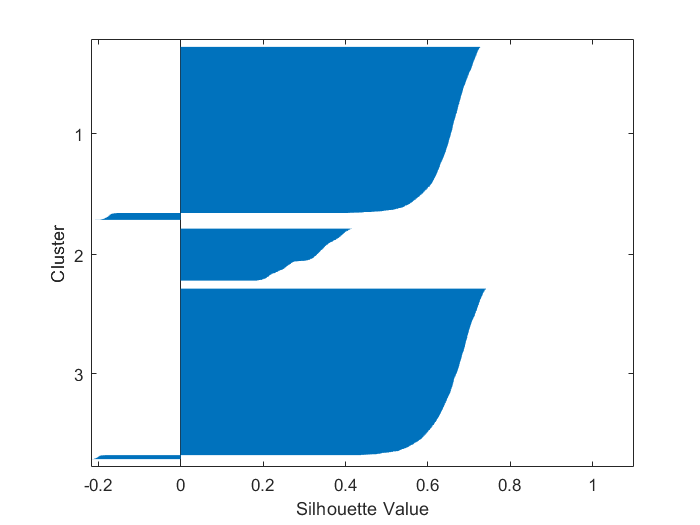

figure
silhouette(X,IDX7,@MixDistance);
figure
silhouette(X,IDX8,@MixDistance);
figure
silhouette(X,IDX9,@MixDistance);

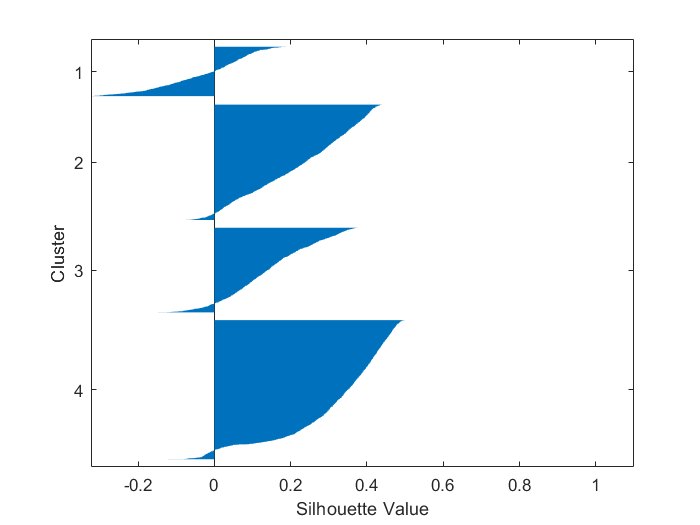

figure
silhouette(X,IDX10,@MixDistance);

### **Conclusions**

The optimal number of clusters is 3 and all three criteria affirm this. Despite this, we would like to have a wider range of years of time horizon and so a larger number of clusters. Therefore we choose to segment clients into 6 clusters and we believe it is a good compromise, especially observing the silhouette plot.

### Analyzing 3 clusters

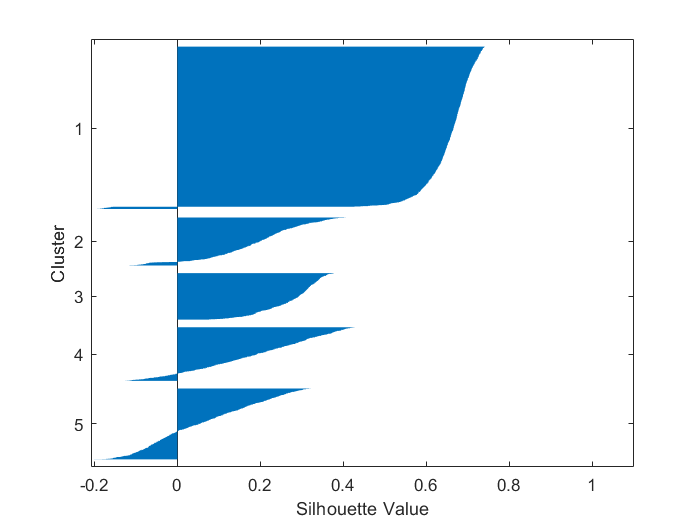

Data4Plot = [Data.Age  Data.FinancialEducation Data.RiskPropensity Data.Income Data.Wealth ];
xnames = {'Age', 'Financial Education', 'Risk propensity', 'Income', 'Wealth'};

gplotmatrix(Data4Plot(1:5000,:),[],IDX3, [],[],[],[],'grpbars', xnames)

We notice that there is a evident linear relationship between *Risk propensity* and *Financial education: *as clients are more acknowledged about financial markets, more they are prone to riskier investments.

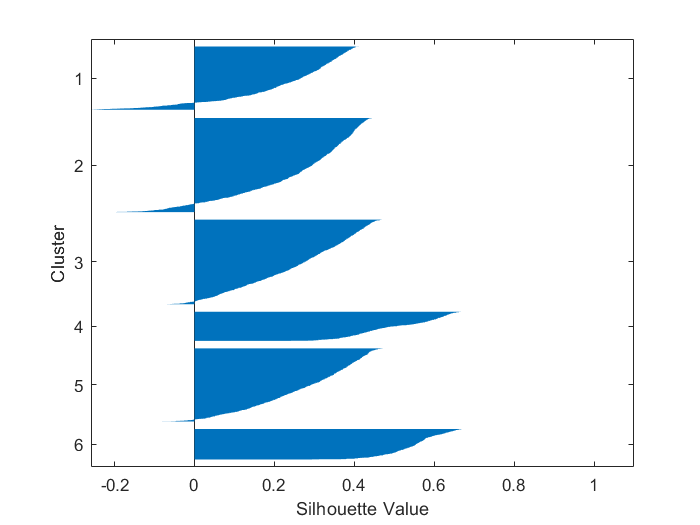

ClusterCardinality = grpstats(X(:, 1),IDX3, 'numel');

ClusterCardinality = ClusterCardinality/sum(ClusterCardinality)

The first and the third clusters are almost equal in size between each other. The second is a bit smaller than the other two.

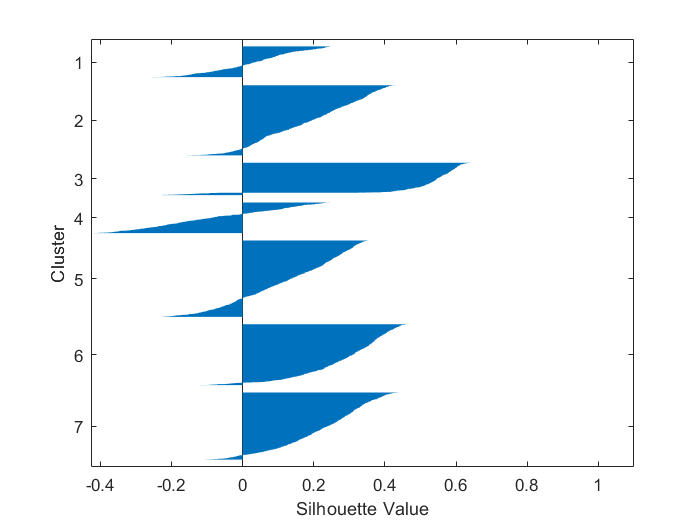

ClusterMedian = grpstats(X(:,6:end),IDX3, @median)

Medians of numerical features look similar between each cluster.

ClusterMeans= grpstats(X(:,1:end),IDX3, 'mean')

### Analyzing 6 clusters

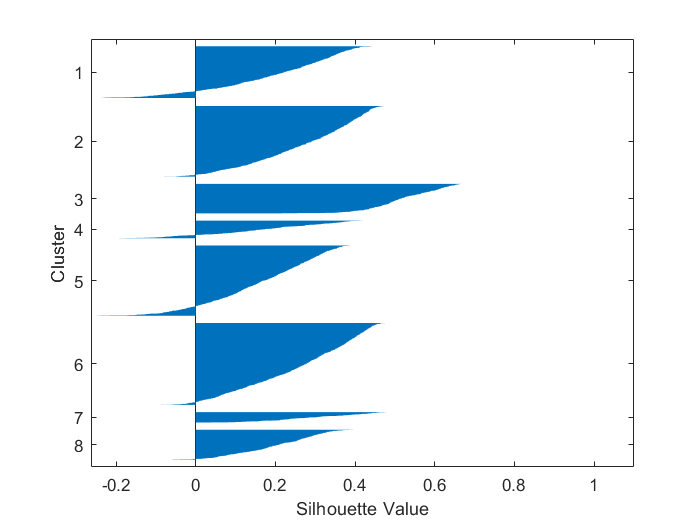

Data4Plot = [Data.Age  Data.FinancialEducation Data.RiskPropensity Data.Income Data.Wealth ];

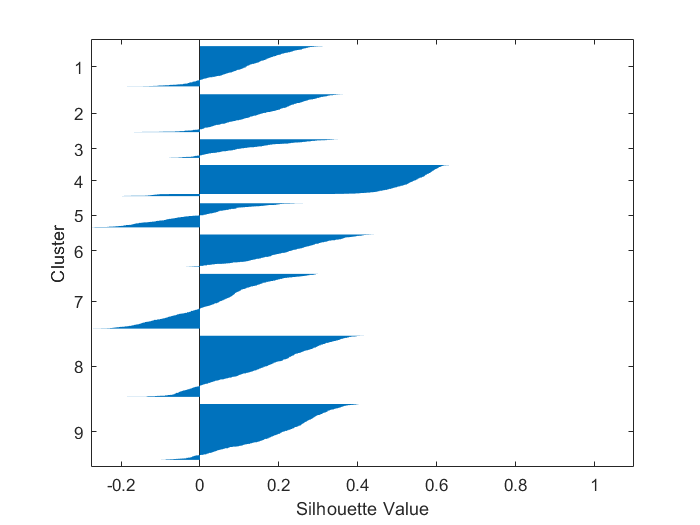

xnames = {'Age', 'Financial Education', 'Risk propensity', 'Income', 'Wealth'};
gplotmatrix(Data4Plot(1:5000,:),[],IDX6, [],[],[],[],'grpbars', xnames)

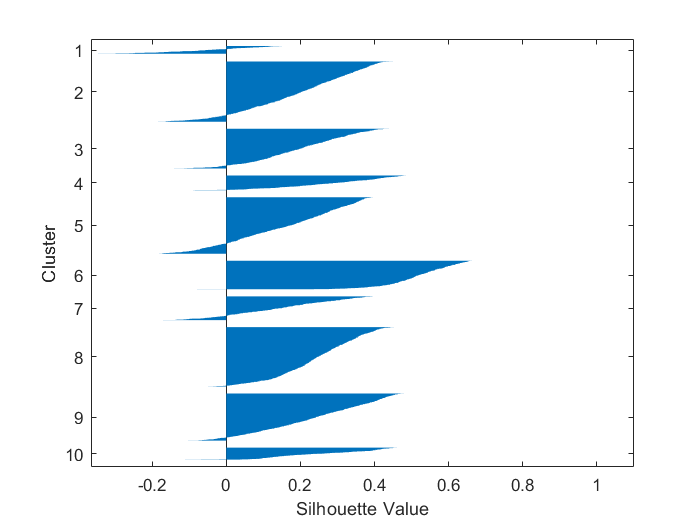

ClusterCardinality = grpstats(X(:, 1),IDX6, 'numel');
ClusterCardinality = ClusterCardinality/sum(ClusterCardinality)

ClusterMedian = 100*grpstats(X(:,6:end),IDX6, @median)

Numerical features are similar among clusters. 

ClusterMeans= grpstats(X(:,1:end),IDX6, 'mean')

We notice that almost every cluster contains an equal amount of females and males.

For what concerns *Family members*, it looks like the data has been clustered moslty based on this feature. Indeed, the second, third and fourth column indicate that each cluster has the total proportion of units (100%) with the same number of family members.

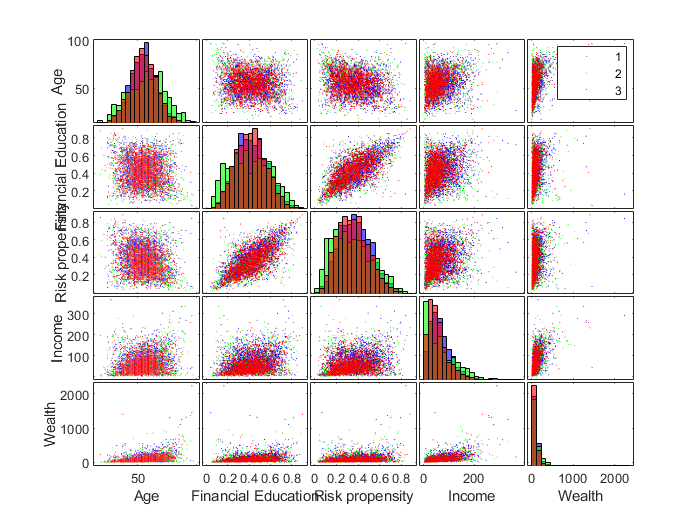

ClusterVariances= grpstats(X(:,1:end),IDX6, 'var')
Clustermins= grpstats(X(:,1:end),IDX6, 'min')

Clustermaxs= grpstats(X(:,1:end),IDX6, 'max')

### Dividing data into 6 clusters

Data.Clusters=IDX6(:,1);

We notice what was expected: cluster 1, 3 and five contain respectively the total amount of units with 2 and 5, 4 and 1 family members. Cluster 2, 4 and 6 contain 3 family members and then we must look at numerical features to check for differences between them. Here we provide a short description of each cluster, by comparing their medians:

- Family members 2/5: quite rich, larger income than wealth;

- Family members 3: very rich, quite old, low risk propensity and low financial education score;

- Family members 4: very rich, middle aged,  mezza età, low risk propensity;

- Family members 3: poorer than other clusters,younger than other clusters 2 and 6, low risk propensity and low financial education score;

- Family members 1: poorer than other clusters, younger than other clusters, larger income than wealth, low risk propensity;

- Family members 3: very rich, high risk propensity and high financial education score.

### Assigning the estimated time horizon of investment to each client

We decided to assign to each cluster a time period in years, between 2 and 7 years. We decided this range for two reasons. 

First of all, the dataset *Products*, that is subsequently used for the association of clients' needs and products, actually contains categories of products. Therefore we define the time horizon of investment as the time period during which the client might invest on the same category of products. Thus we do not assume that the client sticks on the same product for as long as seven years, for example. We assume that he/she might disinvest on one product as long as he/she invests on other products of the same category. This, in our opinion, reflects better the business reality of the financial world.

Secondly, many categories of products such as *Life insurance,* that are present in the dataset* Products, *require a time horizon of investment that is quite long by definition. Therefore our choice seems appropriate for our case.

The assignment is the following one:

- 3 years;

- 2 years;

- 4 years;

- 7 years;

- 5 years;

- 6 years;

The criteria used are the following, in order of importance:

- The younger the person, the greater the time horizon of investment: this seems reasonable as they have a greater life expectancy than older people.

- The higher the risk propensity the greater the time horizon of investment: for long term investments clients can take on more risk, since the market has many years to recover in the event of a pullback.

for i = 1:5000

ClusterCardinality =     0.4384
    0.1314
    0.4302


    if (Data.Clusters(i) == 1) 
        Data.TimeHorizon(i)=3; 

ClusterMedian =     0.4684    0.4387    0.3993    0.6687    0.5554
    0.5063    0.4166    0.3447    0.6501    0.5365
    0.4684    0.4419    0.3730    0.6274    0.5239


    elseif (Data.Clusters(i) == 2) 
        Data.TimeHorizon(i)=2; 

ClusterMeans =     0.4690         0         0    0.9557    0.0392    0.4695    0.4454    0.4094    0.6528    0.5523
    0.6134    0.5890         0         0    0.4110    0.4992    0.4323    0.3716    0.6071    0.5262
    0.4784         0    0.9768         0    0.0232    0.4652    0.4412    0.3848    0.6120    0.5197


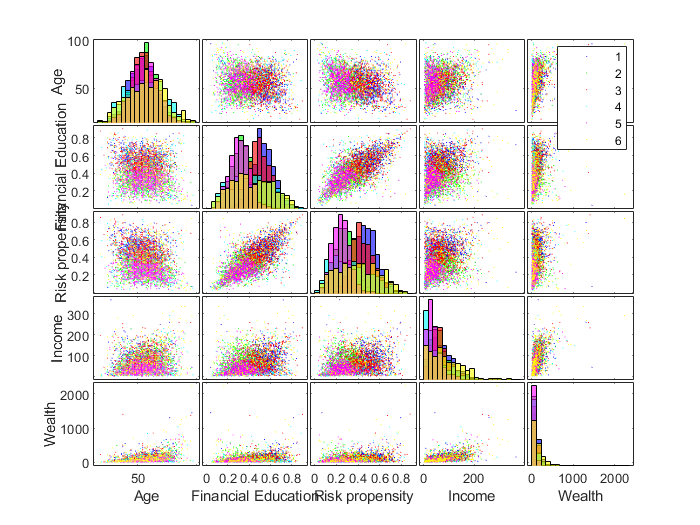

    elseif (Data.Clusters(i) == 3) 
        Data.TimeHorizon(i)=4; 
    elseif (Data.Clusters(i) == 4) 
        Data.TimeHorizon(i)=7; 
    elseif (Data.Clusters(i) == 5) 
        Data.TimeHorizon(i)=5; 

    elseif (Data.Clusters(i) == 6) 
        Data.TimeHorizon(i)=6; 

ClusterCardinality =     0.1704
    0.2506
    0.2256
    0.0774
    0.1946
    0.0814


    end

ClusterMedian =    45.5696   57.4615   53.5436   68.0920   58.3502
   48.1013   34.1086   29.6992   65.7488   52.9369
   45.5696   53.5921   47.8115   67.6299   56.6379
   48.1013   46.1440   32.9954   57.8343   49.3831
   46.8354   31.7223   25.1700   56.5234   48.1582
   50.6329   44.9340   43.1357   70.8829   60.3187


end

NOTE: The order of the clusters changes each time, therefore the above description may not correspond to the dataset obtained.

### Visualizing Time Horizon

hist(Data.TimeHorizon)

ClusterMeans =     0.4566         0         0    0.9883         0    0.4541    0.5737    0.5439    0.6613    0.5812
    0.5092         0         0    1.0000         0    0.4793    0.3452    0.3012    0.6404    0.5255
    0.4468         0    1.0000         0         0    0.4610    0.5493    0.4959    0.6632    0.5646
    0.4806    1.0000         0         0         0    0.4759    0.4505    0.3620    0.5629    0.4831
    0.5396         0    1.0000         0         0    0.4777    0.3183    0.2575    0.5567    0.4714
    0.5356         0         0         0    0.9975    0.4948    0.4529    0.4384    0.6701    0.5855


### Saving this new dataset with the new variable Time Horizon

%NeedsclustTOT=Data;
%save("NeedsclustTOT.mat","NeedsclustTOT");
load("NeedsclustTOT.mat","NeedsclustTOT");

ClusterVariances =     0.2484         0         0    0.0116         0    0.0200    0.0155    0.0143    0.0179    0.0106
    0.2501         0         0         0         0    0.0191    0.0141    0.0118    0.0158    0.0112
    0.2474         0         0         0         0    0.0192    0.0149    0.0176    0.0149    0.0095
    0.2503         0         0         0         0    0.0394    0.0486    0.0428    0.0377    0.0265
    0.2487         0         0         0         0    0.0206    0.0120    0.0110    0.0180    0.0114
    0.2493         0         0         0    0.0025    0.0401    0.0492    0.0494    0.0341    0.0210


Data=NeedsclustTOT; % we load our dataset that we obtained in order to get the same results for the model

Clustermins =          0         0         0         0         0    0.0759         0    0.0260    0.0887    0.0333
         0         0         0    1.0000         0    0.0759    0.0321    0.0312    0.0275    0.0478
         0         0    1.0000         0         0         0    0.1094    0.0779    0.0681         0
         0    1.0000         0         0         0    0.0127    0.0126         0         0    0.0003
         0         0    1.0000         0         0    0.0506    0.0411    0.0105    0.0464    0.0113
         0         0         0         0         0         0    0.0152    0.0004    0.0425    0.0196


### Running the classification model with Time Horizon 

### **Preparing the data**

Data = [Data Needs(:,9:10)];

Clustermaxs =     1.0000         0         0    1.0000         0    0.9873    0.9351    0.8972    1.0000    0.9434
    1.0000         0         0    1.0000         0    0.9747    0.9002    0.7627    0.9139    0.8327
    1.0000         0    1.0000         0         0    0.9747    1.0000    1.0000    0.9362    0.9392
    1.0000    1.0000         0         0         0    1.0000    0.9844    0.9358    0.9581    0.8995
    1.0000         0    1.0000         0         0    0.9367    0.7122    0.8762    0.9043    0.8656
    1.0000         0         0         0    1.0000    0.9873    0.9417    0.9514    0.9835    1.0000


X =[rescale(Data.Age) Data.Gender rescale(Data.FamilyMembers) rescale(Data.FinancialEducation)...
   rescale(Data.RiskPropensity) rescale(logIncome) rescale(logWealth) rescale(Data.TimeHorizon)];

nObs = size(Data, 1);
idxPermutation = randperm(nObs);
X = X(idxPermutation,:); % random permutation
nObsTrain = round(0.75*nObs);

varNames = {'Age', 'Gender', 'Family', 'FinEdu', 'Risk', 'Income', 'Wealth', 'TimeHorizon'};

nObs = size(Data, 1);
IncomeWealthRatio = zeros(nObs,1);
IncomeWealthRatio(Data.Wealth>10) = logIncome(Data.Wealth>10)./logWealth(Data.Wealth>10);

Xsmall = [rescale(IncomeWealthRatio) rescale(Data.Age) rescale(Data.FinancialEducation) logIncome logWealth rescale(Data.TimeHorizon)];

### **Plotting the variables according Accumulation need**

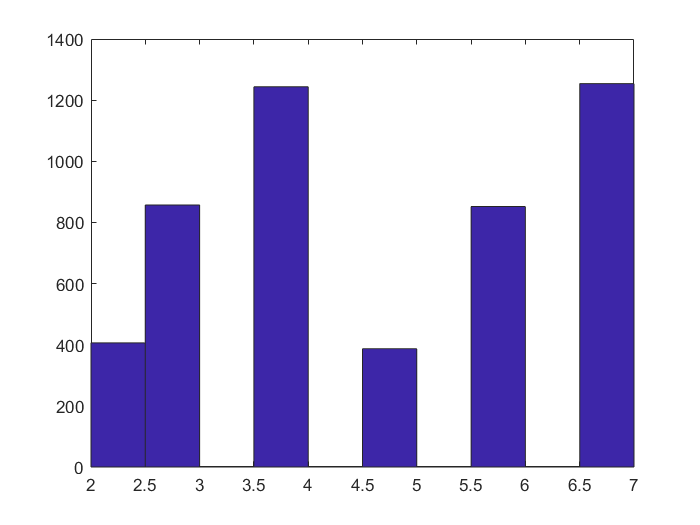

figure

xnames = {'Income/Wealth ratio','Age', 'Financial Education', 'Income', 'Wealth', 'TimeHorizon'};
gplotmatrix(Xsmall,[],Data.AccumulationInvestment, ["c", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Accumulation need')

### **Plotting the variables according Income need**

figure
xnames = {'Income/Wealth ratio','Age', 'Financial Education', 'Income', 'Wealth', 'TimeHorizon'};
gplotmatrix(Xsmall,[],Data.IncomeInvestment, ["c", "k"],[],[],[],'grpbars', xnames)
title('Grouping by Income need')

### **Preparing the data**

XsmallTrain = Xsmall(1:nObsTrain,:);
XsmallTest= Xsmall(nObsTrain+1:end,:);
XsmallTrainTable=table(XsmallTrain(:,1), XsmallTrain(:,2), XsmallTrain(:,3), XsmallTrain(:,4), XsmallTrain(:,5), XsmallTrain(:,6), 'VariableNames',xnames);
yInvIncTrain = Data.IncomeInvestment(1:nObsTrain);
yInvIncTest = Data.IncomeInvestment(nObsTrain+1:end);

yInvAccTrain = Data.AccumulationInvestment(1:nObsTrain);
yInvAccTest = Data.AccumulationInvestment(nObsTrain+1:end);

### **Running the model which classifies Accumulation need**

NOTE: it will take a while.

rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum_acc = fitcensemble(XsmallTrainTable,yInvAccTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

### **Running the model which classifies Income need**

rng('default')
t = templateTree('Reproducible',true); % in order to get reproducible results
MdlOptimum_inc = fitcensemble(XsmallTrainTable,yInvIncTrain,'OptimizeHyperparameters','auto','Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'))

### **Saving the models**

save("model_accTIMEclustTOT.mat","MdlOptimum_acc");
save("model_incTIMEclustTOT.mat","MdlOptimum_inc");

### Evaluating predictions for Accumulation and Income need

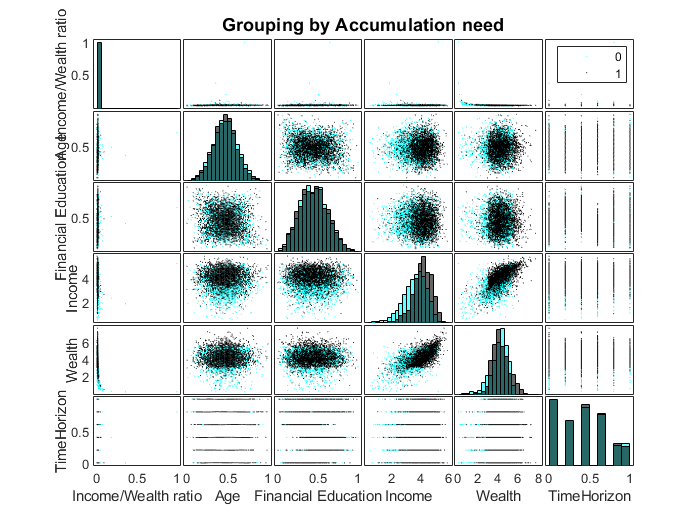

%accumulation need
[labels_acc,scores_acc] = predict(MdlOptimum_acc,XsmallTest);

figure

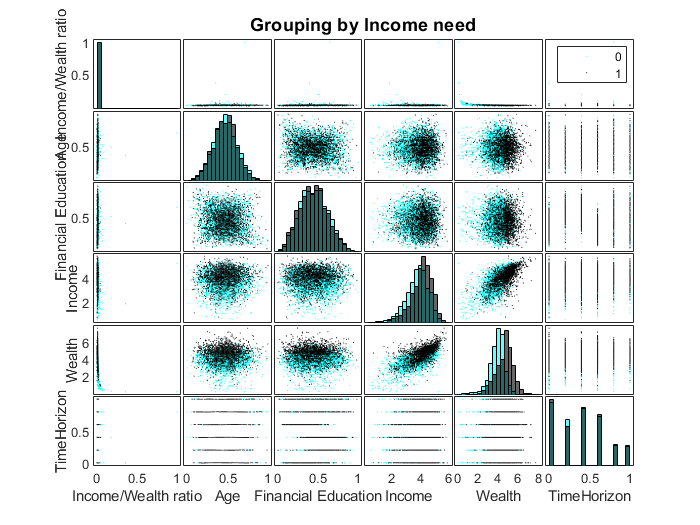

histogram(max(scores_acc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')
%income need

[labels_inc,scores_inc] = predict(MdlOptimum_inc,XsmallTest);

figure
histogram(max(scores_inc')')
title('ArgMax[scores = pseudo-probabilities]')
xlabel('Score')
ylabel('Absolute frequency')

### Precision, recall and F1 score for Accumulation need

%accumulation 
tp_acc = sum((labels_acc == '1') & (yInvAccTest=='1'));
fp_acc = sum((labels_acc == '1') & (yInvAccTest=='0'));
fn_acc = sum((labels_acc == '0') & (yInvAccTest=='1'));
prec_acc = tp_acc / (tp_acc + fp_acc)
rec_acc = tp_acc / (tp_acc + fn_acc)
F1_acc = 2 * prec_acc * rec_acc / (prec_acc + rec_acc)

The results are similar to the model with the random assignment of Time Horizon, therefore our subdivision has not improved much the quality of the model, that is already pretty good.

### Precision, recall and F1 score for Income need

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |       0.276 |      5.6564 |       0.276 |       0.276 |   AdaBoostM1 |          123 |    0.0018985 |          455 |
|    2 | Best   |      0.2184 |       3.872 |      0.2184 |     0.22168 |   AdaBoostM1 |           96 |      0.19715 |           16 |
|    3 | Best   |     0.21653 |      1.2817 |     0.21653 |     0.21821 |          Bag |           12 |            - |           18 |
|    4 | Accept |     0.30213 |       1.018 |     0.21653 |   

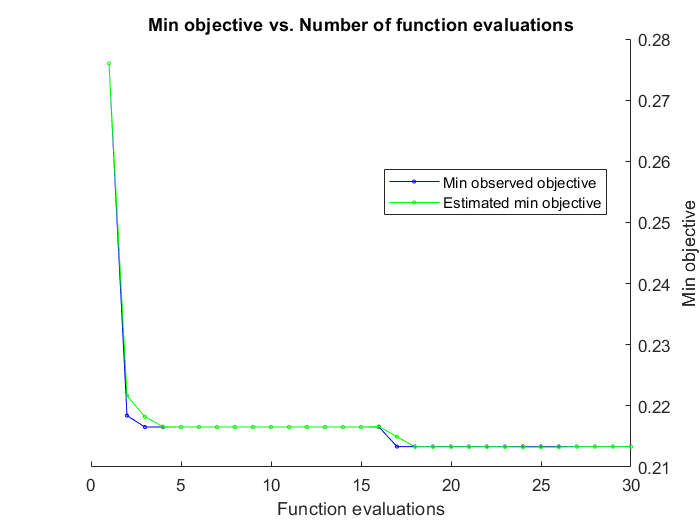


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 168.1398 seconds
Total objective function evaluation time: 136.5463

Best observed feasible point:
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    ___________

     Bag             498              NaN            8     

Observed objective function value = 0.21333
Estimated objective function value = 0.21332
Function evaluation time = 30.0097

Best estimated feasible point (according to models):
    Method    NumLearningCycles    LearnRate    MinLeafSize
    ______    _________________    _________    

MdlOptimum_acc =   ClassificationBaggedEnsemble
                       PredictorNames: {'Income/Wealth ratio'  'Age'  'Financial Education'  'Income'  'Wealth'  'TimeHorizon'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 3750
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 498
                               Method: 'Bag'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: []
                   FitInfoDescription: 'None'
                            FResample: 1
                              Replace: 1
                     Us

%income 
tp_inc = sum((labels_inc == '1') & (yInvIncTest=='1'));

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |      0.2424 |      3.1689 |      0.2424 |      0.2424 |   AdaBoostM1 |          123 |    0.0018985 |          455 |
|    2 | Best   |      0.2216 |      3.0706 |      0.2216 |     0.22279 |   AdaBoostM1 |           96 |      0.19715 |           16 |
|    3 | Accept |     0.22213 |     0.69803 |      0.2216 |     0.22218 |          Bag |           12 |            - |           18 |
|    4 | Accept |      0.2424 |     0.62765 |      0.2216 |   

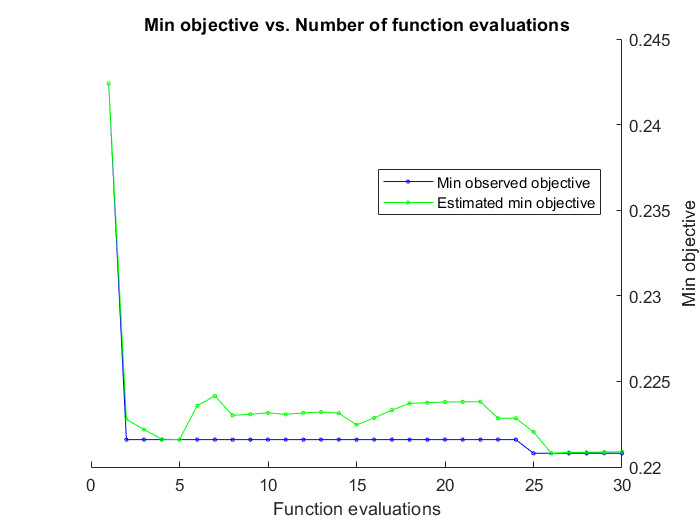


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 182.0149 seconds
Total objective function evaluation time: 154.7973

Best observed feasible point:
      Method      NumLearningCycles    LearnRate    MinLeafSize
    __________    _________________    _________    ___________

    AdaBoostM1           481           0.0028503        42     

Observed objective function value = 0.2208
Estimated objective function value = 0.22089
Function evaluation time = 15.6887

Best estimated feasible point (according to models):
      Method      NumLearningCycles    LearnRate    MinLeafSize
    __________    _________________    _______

MdlOptimum_inc =   ClassificationEnsemble
                       PredictorNames: {'Income/Wealth ratio'  'Age'  'Financial Education'  'Income'  'Wealth'  'TimeHorizon'}
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0    1]
                       ScoreTransform: 'none'
                      NumObservations: 3750
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                           NumTrained: 481
                               Method: 'AdaBoostM1'
                         LearnerNames: {'Tree'}
                 ReasonForTermination: 'Terminated normally after completing the requested number of training cycles.'
                              FitInfo: [481×1 double]
                   FitInfoDescription: {2×1 cell}


  Propertie

fp_inc = sum((labels_inc == '1') & (yInvIncTest=='0'));
fn_inc = sum((labels_inc == '0') & (yInvIncTest=='1'));
prec_inc = tp_inc / (tp_inc + fp_inc)
rec_inc = tp_inc / (tp_inc + fn_inc)
F1_inc = 2 * prec_inc * rec_inc / (prec_inc + rec_inc)

NeedsclustTOT=Data;
save("NeedsclustTOT.mat","NeedsclustTOT");

The results are similar to the model with the random assignment of Time Horizon, therefore our subdivision has not improved much the quality of the model, that is already pretty good.

### ROC curve

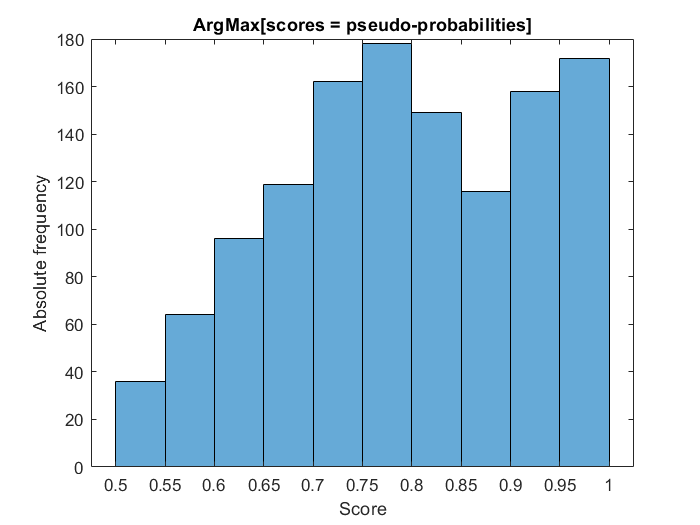

[X_acc,Y_acc,T_acc,AUC_acc,OPTROCPT_acc] = perfcurve(yInvAccTest,scores_acc(:,2),1);
%area under curve
AUC_acc
plot(X_acc,Y_acc)
hold on
plot(OPTROCPT_acc(1),OPTROCPT_acc(2),'ro')
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees for Accumulation Need')
hold off
%optimal operating point accumulation

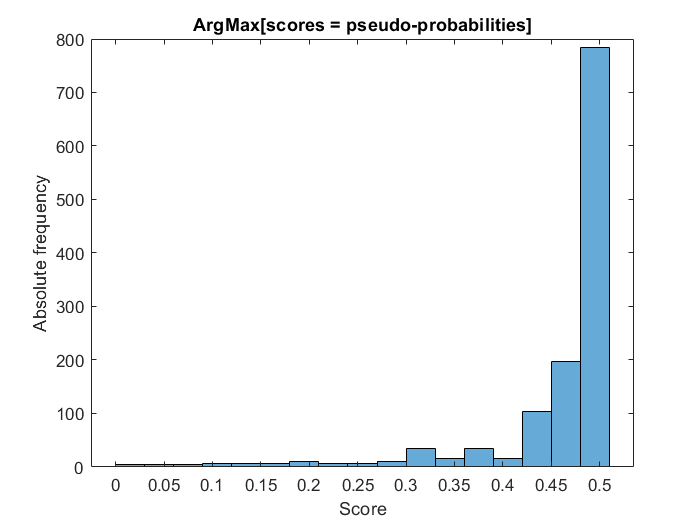

OPTROCPT_acc
%threshold of the optimal operating point
T_acc((X_acc==OPTROCPT_acc(1))&(Y_acc==OPTROCPT_acc(2)))
%income
[X_inc,Y_inc,T_inc,AUC_inc,OPTROCPT_inc] = perfcurve(yInvIncTest,scores_inc(:,2),1);
%area under curve
AUC_inc
plot(X_inc,Y_inc)

hold on
plot(OPTROCPT_inc(1),OPTROCPT_inc(2),'ro')
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC Curve for Classification by Classification Trees for Income Need')
hold off

prec_acc = 0.9016

%optimal operating point accumulation

rec_acc = 0.6887

OPTROCPT_inc

F1_acc = 0.7809

%threshold of the optimal operating point
T_inc((X_inc==OPTROCPT_inc(1))&(Y_inc==OPTROCPT_inc(2)))

The ROC curves show the goodness-of-fit of the model considered. It plots the trade-off between sensitivity (or TPR) and specificity (1 – FPR). 

This curve confirm that our models provide an accurate classification. Moreover the value of the AUC is very close to 1 in both cases.

We observe that the classification of accumulation needs is a bit more accurate than the income ones.

### Confusion matrices

% Accumulation
%  Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary. 
%  Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.
confusionchart(yInvAccTest,labels_acc,'RowSummary','row-normalized','ColumnSummary','column-normalized');
%Income

prec_inc = 0.9078

%  Specify 'RowSummary' as 'row-normalized' to display the true positive rates and false positive rates in the row summary. 

rec_inc = 0.5235

%  Also, specify 'ColumnSummary' as 'column-normalized' to display the positive predictive values and false discovery rates in the column summary.

F1_inc = 0.6641

confusionchart(yInvIncTest,labels_inc,'RowSummary','row-normalized','ColumnSummary','column-normalized');

In both cases the model could be improved by reducing the number of false positives: is predicted 0 (no need of accumulation or income product) instead of a true 1 (a need in one of the two).

### Trees

We now show the tree number 20 of our models.

view(MdlOptimum_acc.Trained{20},'Mode','graph')

In this case the tree looks quite complex. It is noticeable that *Income/Wealth ratio, Age and Wealth* are the most important variables, since they are close to the root of the tree. *Time Horizon* is used in the tree, even though it does not have particular relevance.

AUC_acc = 0.8295

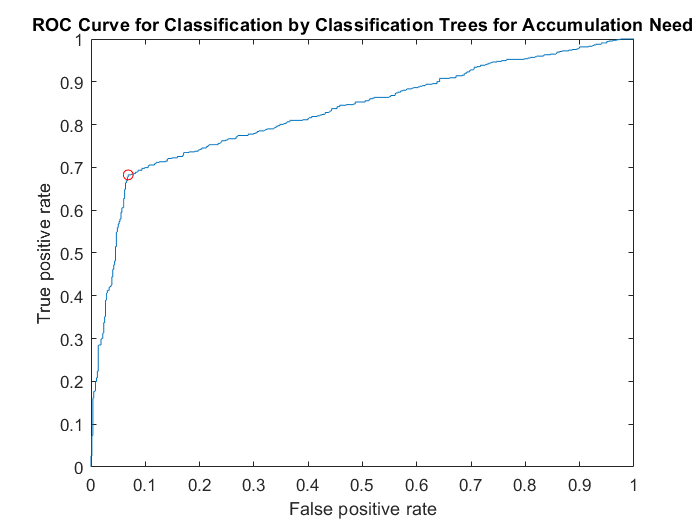

OPTROCPT_acc =     0.0686    0.6825


ans = 0.5382

AUC_inc = 0.7660

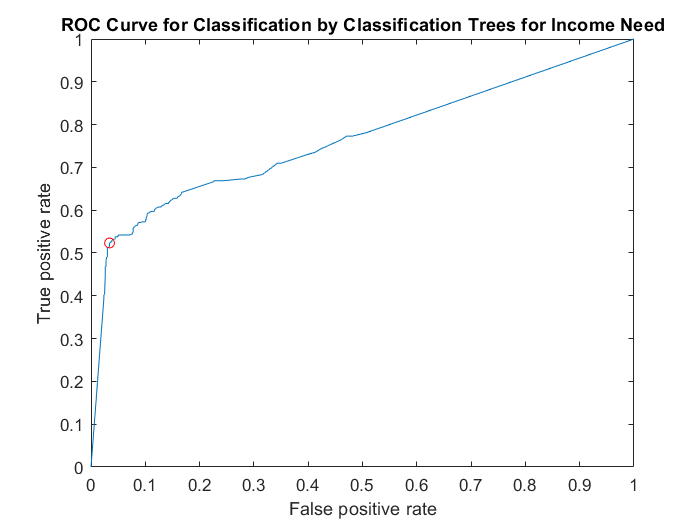

OPTROCPT_inc =     0.0342    0.5235


ans = 0.0186

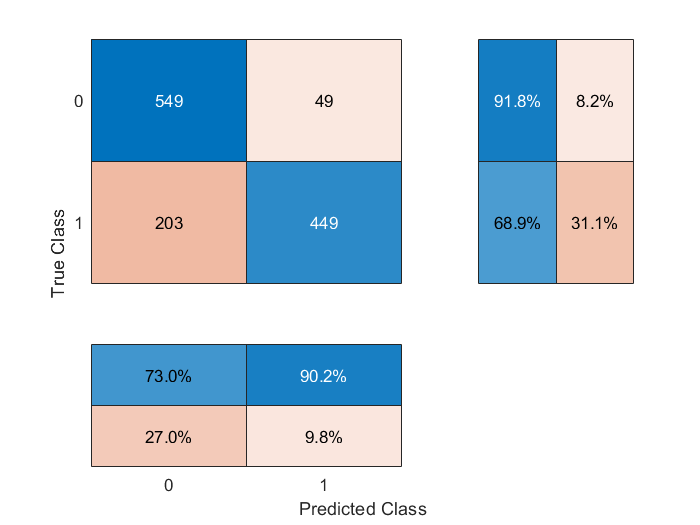

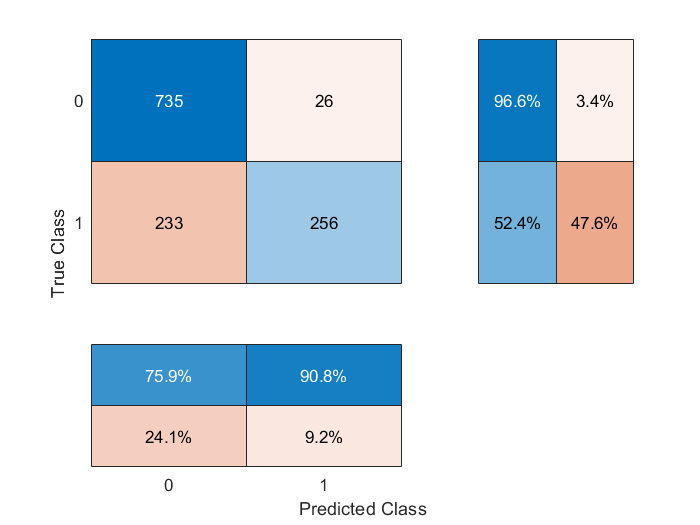

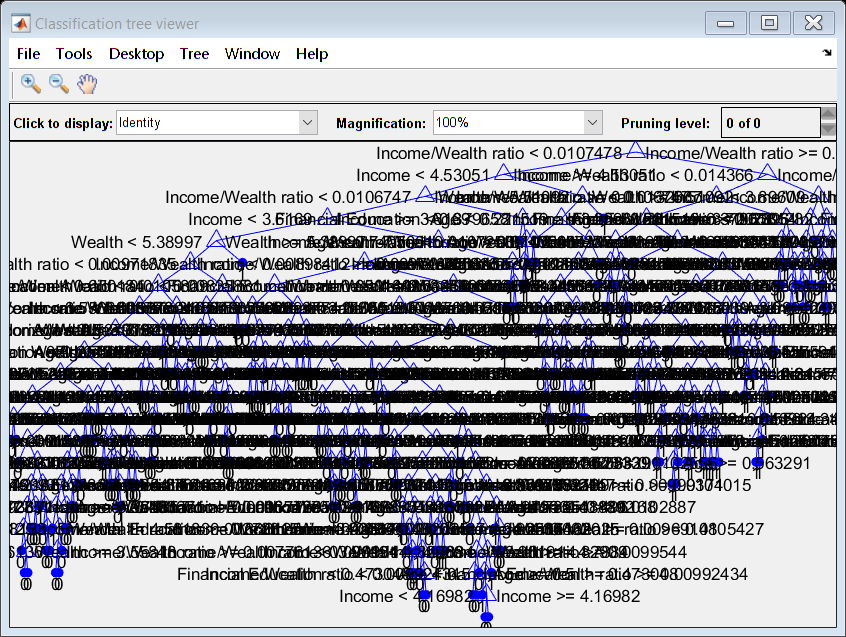

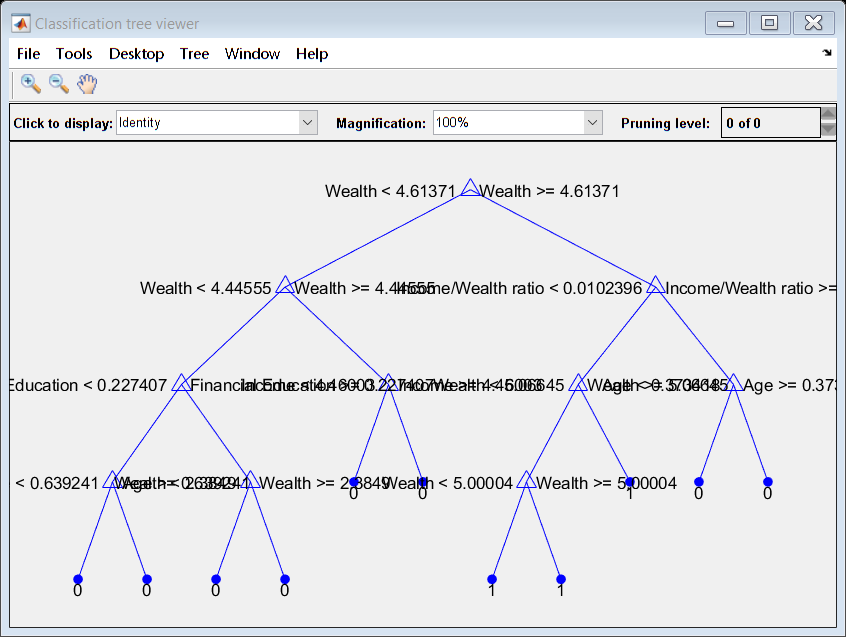

view(MdlOptimum_inc.Trained{20},'Mode','graph')

We notice that in also in this case the most important variables are *Wealth, Age and Income/Wealth ratio.*